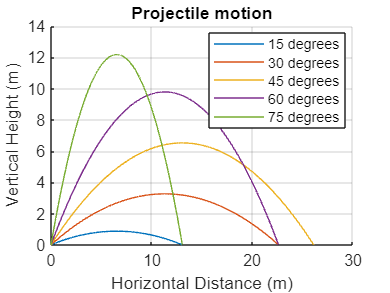

velocity = 16;
figure;
hold on;

angles = 15:15:75;  % Specify angles in degrees

g = 9.81;  % Acceleration due to gravity

for angle = angles
    Vyi = velocity * sind(angle);
    Vxi = velocity * cosd(angle);
    
    tmax = (2 * Vyi / g);  % Calculate the time of flight

    % Generate time points from 0 to tmax with smaller steps
    t = 0:0.001:tmax;

    % Calculate horizontal distance and vertical height
    x = Vxi * t;
    d = 0 + Vyi * t - 0.5 * g * t.^2;

    % Plot the trajectory
    plot(x, d, 'DisplayName', [num2str(angle), ' degrees']);
end

grid on;
legend('Location', 'best');
title('Projectile motion');
xlabel('Horizontal Distance (m)');
ylabel('Vertical Height (m)');